clear
close all
clc


% load 
fileName = 'DemoDataSJ' ;
load(fileName) ;


# **データの確認：　構造体**

動作データ（Markers） は、構造体というデータタイプとして格納されている

ワークスペースから Markers をクリックすると、'フィールド' と '値' がペアとなったデータとなっている

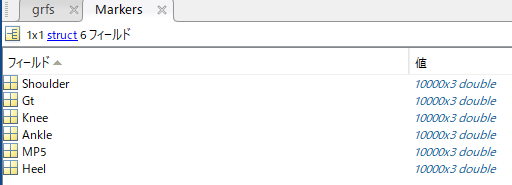

※　必ずしも構造体を用いる必要はないが、適切に構造体を用いることで、コードが見やすくなる

※　markers(:,9) だとどこのマーカーか良く分からないが、Markers.Knee(:,3) と書いてあれば、膝の z 座標ぽい

# **マーカー座標の時系列データをプロットする**

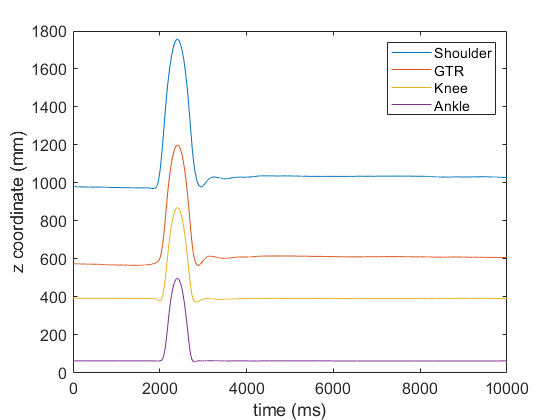

figure
plot(Markers.Shoulder(:,3)) ; hold on % Shoulder マーカーの z 座標をプロット

% ///// 他のマーカーの時系列データもプロットするプログラムを書いてください /////



% /////

% 軸ラベル・凡例
legend({'Shoulder', 'GTR', 'Knee', 'Ankle'})
ylabel('z coordinate (mm)')
xlabel('time (ms)')
set(gca, 'fontsize', 12, 'fontname', 'arial')

# **床反力とマーカー座標を、あわせてプロットする**

subplot 関数を持ちいて、複数のパネルを持った figure が作成できる

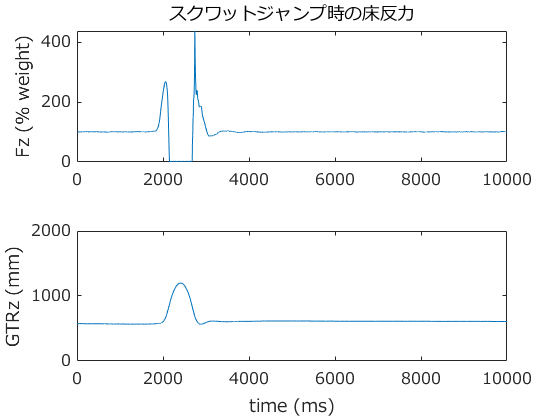

% 床反力データ

% ///// 床反力鉛直成分の両足の合計を fz と定義するコードを書いてください /////




% /////


fzPercentWeight = fz * 100 ; % 100倍した方がグラフ的に見やすい説　（分かりやすい変数名にしておくこと）

% プロット
figure
subplot(2,1,1) ;
plot(fzPercentWeight)
ylabel('Fz (% weight)')
set(gca, 'fontsize', 12, 'fontname', 'meiryo')
title('スクワットジャンプ時の床反力')

subplot(2,1,2) ;
plot(Markers.Gt(:,3)) ;
set(gca, 'ylim', [0, 2000]) ; % y軸の範囲を指定
ylabel('GTRz (mm)')
xlabel('time (ms)')
set(gca, 'fontsize', 12, 'fontname', 'meiryo')